%计算考虑化学作用后的三锁体系
clear all
syms e r o ;

y1=[];
y2=[];
Plock=[];
Vlock=[];
Vopen=[];

%笼腔长度等于多少个sigma(o)
l=4;

hold on 
for l = 4:0.1:6
%计算锁死所占成分
    fun1 = @(x1,x2,x3) P(x3).^2.*P(x2-x3).^2.*P(x1-x2).^2.*P(l-x1);
    x3max= @(x1,x2) 1*x2;
    x2max= @(x1) 1*x1;
    V_lock = 4*integral3(fun1,0,l,0,x2max,0,x3max);
    Vlock=[Vlock,V_lock];
%计算开放所占成分
    fun2 = @(x1,x2,x3) P(l-x3).*P(x3).*P(x2-x3) ...
        .*P(x1-x2).*P(l-x1).*P(x2).*P(x1-x2);
    x3max= @(x1,x2) 1*x2;
    x2max= @(x1) 1*x1;
    V_open1 = 2*integral3(fun2,0,l,0,x2max,0,x3max);
    fun3 = @(x1,x2,x3) P(l-x2).*P(x3).*P(x2-x3) ...
        .*P(x1-x2).*P(l-x1).*P(x3).*P(x1-x3);
    x3max= @(x1,x2) 1*x2;
    x2max= @(x1) 1*x1;
    V_open2 = 2*integral3(fun3,0,l,0,x2max,0,x3max); 
    V_open=V_open1 + V_open2;
    Vopen=[Vopen,V_open];
end

V_open = 0.0012

V_open = 0.3042

V_open = 12.0916

V_open = 128.3970

V_open = 493.0052

V_open = 1.0446e+03

V_open = 1.5518e+03

V_open = 1.8675e+03

V_open = 1.9980e+03

V_open = 2.0147e+03

V_open = 1.9828e+03

V_open = 1.9414e+03

V_open = 1.9088e+03

V_open = 1.8914e+03

V_open = 1.8896e+03

V_open = 1.9019e+03

V_open = 1.9259e+03

V_open = 1.9596e+03

V_open = 2.0010e+03

V_open = 2.0486e+03

V_open = 2.1013e+03

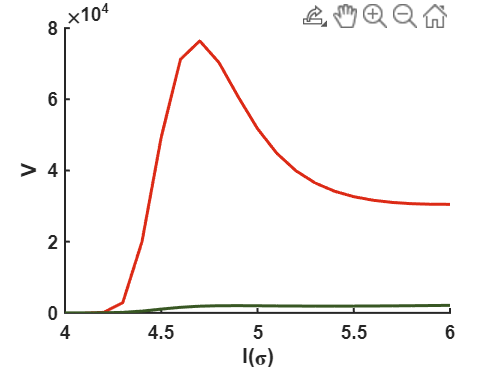



%画出锁死概率随l的变化
length=[4:0.1:6];
plot(length, Vlock,'LineWidth',1.5, ...
    'color',[221, 42, 22]/256)
plot(length, Vopen,'LineWidth',1.5, ...
    'color',[56, 87, 35]/256)
hold off

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('V','FontName','arial','FontWeight','bold');

function a= E(r) %定义特定的势能函数E(r)
    e=5500;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end